# **Example of Streamer data processing**

## Introduction

**Authors**: I. Abakumov, 

**Publication date**: 22nd of October 2019

**E-mail**: ivan.abakumov@fu-berlin.de

## Upload MLIB library

clear; close all; clc;
mlibfolder = '/data/ivan/share/MLIB/';
path(path, mlibfolder);
add_mlib_path;
%https://github.com/Abakumov/MLIB


## Set size of the grid

G=GridClass;

% [m]        [m]          [m]          [s]
G.x0=0;     G.y0=0;   G.z0=0;         G.t0 = 0.0;           % initial point
G.nx=1840;  G.ny=1;   G.nz=300;       G.nt = 8001;          % grid size
G.dx=100;   G.dy=1;   G.dz=100;       G.dt = 0.002;         % grid step (meter)

G.gridInfo;

Information about grid:
x0=0, dx=100, Nx=1840.
y0=0, dy=1, Ny=1.
z0=0, dz=100, Nz=300.
t0=0, dt=0.002, Nt=8001.


G.setGrid;
Gold = oldGrid(G);

## Apply fk filtering in SU

required = 0; 
if(required)
    for i = 1001:2401
        sufilein = ['/remote/data/ivan/Streamer/data/MC15_' num2str(i) '.su'];
        sufileout = ['/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_' num2str(i) '.su'];
        if exist('sufilein','file') == 0 
            setenv('SUFNAMEIN', sufilein); 
            setenv('SUFNAMEOUT', sufileout); 
            %!echo $SUFNAMEIN
            %!echo $SUFNAMEOUT
            !sudipfilt < $SUFNAMEIN amps=0,0,1,1,0,0 slopes=-0.002,-0.001,-0.0008,0.0008,0.001,0.002 dx=12.5 > $SUFNAMEOUT
        else 
            disp(['Worning: no file'])
            disp('sufilein')
        end
    end

sudipfilt < $SUFNAMEIN amps=0,0,1,1,0,0 slopes=-0.002,-0.001,-0.0008,0.0008,0.001,0.002 dx=12.5 > $SUFNAMEOUT: Interrupt

sudipfilt: fgettr.c: bad first header


end

## Load SU data

data  = read_su_file('/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_2401.su');

/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_2401.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_2401.sgy


traces = data.traces; 
headers = get_segy_headers(data);

## Example of raw data

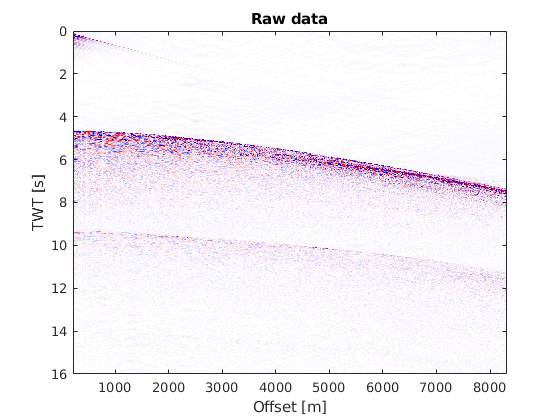

figure(1)
imagesc(headers.offset,G.tt,traces)
%pcolor(headers.offset,G.tt,traces)
%shading interp; 
%set(gca, 'YDir','reverse')
caxis([-10 10])
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
xlabel('Offset [m]')
ylabel('TWT [s]')
title('Raw data')

## Data preprocessing

required = 0; 
if(required)
    STALTAtraces = zeros(size(traces));
    
    tic
    for i=1:648
    
        trace = traces(:,i);
        
        Nl = 125;               % sum range for LTA  500 ms 
        Ns = 35;                % sum range for STA  60 ms
        STA = movmean(trace.^2,[0, Ns-1]);
        LTA = movmean(trace.^2,[Nl-1, 0]);
        STALTA = STA./LTA;
        STALTA(1:Ns) = 0;
        STALTAtraces(:,i) = STALTA;
    end
    toc
end

## Plot STALTA traces

required = 0; 
if(required)
    figure(2)
    %S = SME(STALTAtraces,20);
    imagesc(headers.offset,G.tt,STALTAtraces)
    %pcolor(headers.offset,G.tt,traces)
    %shading interp; 
    %set(gca, 'YDir','reverse')
    caxis([0 20])
    colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
    xlabel('Offset [m]')
    ylabel('TWT [s]')
    title('Raw data')
end

## Load Velocity model

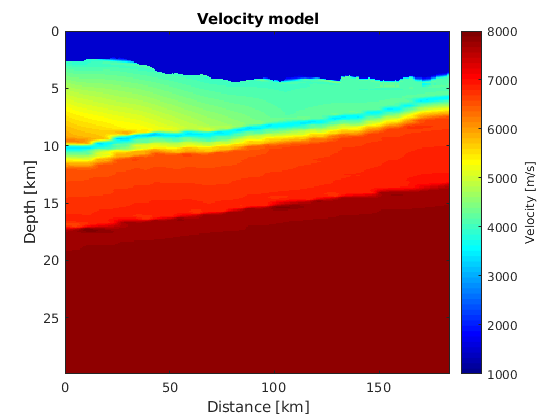

velmod  = read_segy_file('/home/ivan/Desktop/MLIB/Examples/Streamer_data_processing/Velocity_model.sgy');
velmod = velmod.traces'; 

figure(3)
imagesc(G.xx/1000,G.zz/1000,velmod')
%pcolor(headers.offset,G.tt,traces)
%shading interp; 
%set(gca, 'YDir','reverse')
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Velocity model')
c = colorbar;
c.Label.String = 'Velocity [m/s]';
caxis([1000 8000]); 
colormap('jet')
%axis('equal')
axis([G.x0/1000 G.mx/1000 G.z0/1000 G.mz/1000])

%% Part II. Generate Migration 

TTI = zeros(G.nx,G.nz,G.nx);
tic
for i = 1:G.nx
    S = [G.xx(i), 0, 0];
    TTI(:,:,i) = FSM2D(Gold,S,velmod);
end
toc

Elapsed time is 149.351583 seconds.


tic
I = zeros(G.nx,G.nz);
filter = ones(G.nt, 1);
filter(1:2000) = 0;
filter(2000:2100) = (sin(linspace(0,pi/2,101))).^2;
filter(7901:8001) = (sin(linspace(-pi/2,0,101))).^2;  

for i = 1501:2:2001
    sufileout = ['/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_' num2str(i) '.su'];
    if exist(sufileout,'file') == 2 
        data  = read_su_file(sufileout);
        traces = data.traces; 
        headers = get_segy_headers(data);
        scalco = 100;                        
        headers.sx = headers.sx/scalco; 
        headers.rx = headers.rx/scalco; 
        headers.cdpx = (headers.sx+headers.rx)/2;
        acq.sx = headers.sx; 
        acq.sz = 12*ones(size(headers.sx)); 
        acq.rx = headers.rx; 
        acq.rz = 9*ones(size(headers.sx));
        acq.gsx = x2grid(acq.sx,G.x0,G.dx,G.nx);
        acq.grx = x2grid(acq.rx,G.x0,G.dx,G.nx);
        acq.gsz = x2grid(acq.sz,G.z0,G.dz,G.nz);
        acq.grz = x2grid(acq.rz,G.z0,G.dz,G.nz);
        
        sind = acq.gsx(j);
        stti = TTI(:,:,sind);
        
        for j = 1:size(traces,2)
            u = traces(:,j);
            u = u.*filter; 
    
            rind = acq.grx(j);
            rtti = TTI(:,:,rind);
            tti = stti + rtti;
            amp = 1./(tti+G.dt).^2;
            
            tti = x2grid(tti,G.t0,G.dt,G.nt);
            I = I + amp.*u(tti); 
        end
        disp(num2str(i))
    else
        disp('Worning: no file')
        disp('sufileout')
    end
end

1001
1101
1201
1301
1401
1501
1601
1701
1801
1901
2001
2101
2201
2301
2401


toc

Elapsed time is 61.355214 seconds.




%  tind = floor(tti/G.dt) + 1;
%  dtti = tti/G.dt - floor(tti/G.dt);
%  image = image + amp.*((1-dtti).*U(tind) + dtti.*U(tind+1));


